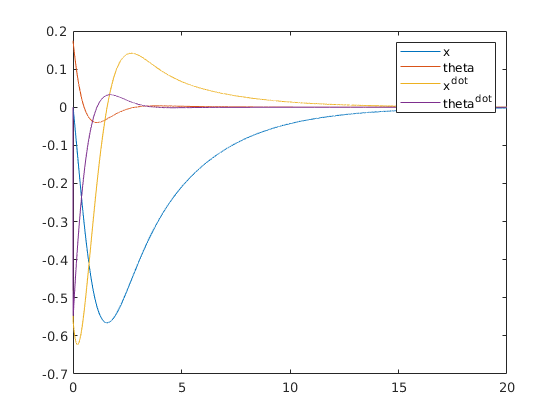

mc=1.5;
mp=0.5;
g=9.82;
L=1;
d1=0.01;
d2=0.01;

A=[0 0 1 0;
    0 0 0 1;
    0 (g*mp)/mc -(d1)/mc -(d2)/(L*mc);
    0 g*(mc+mp)/(L*mc) -(d1)/(L*mc) -(d2*(mc+mp))/(L*L*mc*mp)];

B= [0; 0; 1/mc; 1/(L*mc)];

% consider <x>=[q1 q2 q1' q2']
% q1=distance from origin
% q2=angle of pendulum rod from top

%inverted pendulum cart is unstable by itself despite the top up position
%of pendulum being a fixed point.

% Taking q1 as measured state for the system the system becomes 
C=[1 0 0 0];
D=0;

% the system was already checked to be controllabe because rank_of_ctrb=4=n
rank_of_ctrb = rank(ctrb(A,B));

%For observing only q2(angle) we had seen that system is not observable, but for
%observing only q1(position from origin) the system comes out to be
%controllable.
rank_of_obsv = rank(obsv(A,C));

%for a controllable system I can place the the poles of the controlled
%system X'=(A-BK)X at the position of my choice, however it is best to
%place the poles using the LQR. But for using LQR we need to define the
%penalty function. The penalty function has Q and R which can be regulated
%as per our choice for best functioning of system.

%let me assume
Q = [1 0 0 0;
    0 1 0 0;
    0 0 10 0;
    0 0 0 100];

R = .0001; %for aggresive actuation R needs to be small

K = lqr(A,B,Q,R);

A1=(A-B*K);

% now the system of ODE to be solved is (X')=A1*(X)
intial = [0; (10*pi)/180; 0; 0]; %Let initial value of angle be 10degree as in Assignment 2 and rest all be 0
%we can however alter these values as per our choice
interval = [0 20];
[t, y] = ode45(@(t,y)equation(t,y,A1), interval, intial); 
plot(t,y(:,1),'-',t,y(:,2),'-',t,y(:,3),'-',t,y(:,4),'-'), legend('x','theta','x^d^o^t','theta^d^o^t');